##  Задание 1. Синтез регулятора с заданной степенью устойчивости. 

Начальные условия на задание:

A = [12, -1, 14; 
     6, 0, 6;
     -6, -2, -8]

A =     12    -1    14
     6     0     6
    -6    -2    -8


B = [11;
      7;
      -7]

B =     11
     7
    -7


Найти собственные числа матрицы A и определить управляемость каждого из них. Сделать вывод об управляемости и стабилизируемости системы.

U = ctrb(A, B)

U =     11    27   -36
     7    24    18
    -7   -24   -18


U = [B , A*B , A^2 * B]

U =     11    27   -36
     7    24    18
    -7   -24   -18


rank(U)

ans = 2

Проверка критерия Хаутуса:

EIG_A = eig(A)

EIG_A =    3.0000 + 3.0000i
   3.0000 - 3.0000i
  -2.0000 + 0.0000i


l1 = 3 + 3j; l2 = 3 - 3j; l3 = -2;

vpa([A - eye(3).*l1 , B])

$$ans = \left(\begin{array}{cccc} 9.0-3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0-3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0-3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l2 , B])

$$ans = \left(\begin{array}{cccc} 9.0+3.0\,\mathrm{i} & -1.0 & 14.0 & 11.0\\ 6.0 & -3.0+3.0\,\mathrm{i} & 6.0 & 7.0\\ -6.0 & -2.0 & -11.0+3.0\,\mathrm{i} & -7.0 \end{array}\right)$$

vpa([A - eye(3).*l3 , B])

$$ans = \left(\begin{array}{cccc} 14.0 & -1.0 & 14.0 & 11.0\\ 6.0 & 2.0 & 6.0 & 7.0\\ -6.0 & -2.0 & -6.0 & -7.0 \end{array}\right)$$


rank([A - eye(3).*l1 , B])

ans = 3

rank([A - eye(3).*l2 , B])

ans = 3

rank([A - eye(3).*l3 , B])

ans = 2

**A --> Стабилизируема, но не управляема**

Максимально возможная степень устойчивость, которую можем добиться: -2

C = [1 1 1];
x0 = [1 1 1]';
simTimeStart = 0;
simTimeEnd = 3;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

Не управляемые собственные числа нам не достичь, поэтому они должны в наборе остаться...

В моём случае lambda = -2 неуправляемо, значит оно должно быть в наборе...

Выберем пару значений желаемой степени устойчивости **alpha > 0**

## **Первый выбор альфа**

alpha = 2; % desired decay rate

% Lyapunov inequality
cvx_begin sdp
variable P(3,3) symmetric  % Declare P as symmetric
P >= 0.0001 * eye(3);
variable Y(1,3) 

P*A' + A*P + 2*alpha*P + Y'*B' + B*Y <= 0;
cvx_end

 
Calling SDPT3 4.0: 15 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of free   var  =  3 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.3e+02|2.0e+02|4.2e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.914|0.882|2.8e+01|2.4e+01|2.6e+02| 0.000000e+00  4.377611e-03| 0:0:00| chol  1  1 
 2|0.919|0.926|2.3e+00|1.8e+00|1.7e+01| 0.000000e+00  4.681254e-03| 0:0:00| chol  1  1 
 3|0.962|0.866|8.7e-02|2.4e-01|2.0e+00| 0.000000e+00  2.913919e-03| 0:0:00| 

K = Y*P^-1

K =    10.0658   -8.8314    9.2568



EIG_K1 = eig(A+B*K) % K1

EIG_K1 =   -4.9465 + 7.7790i
  -4.9465 - 7.7790i
  -2.0000 + 0.0000i


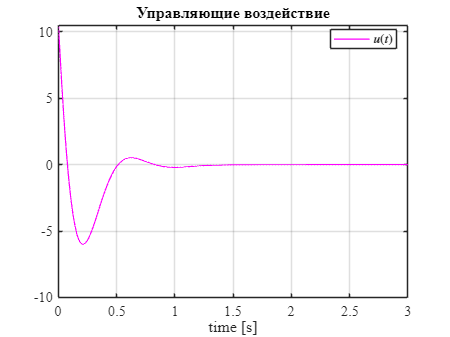



out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl1_u1");

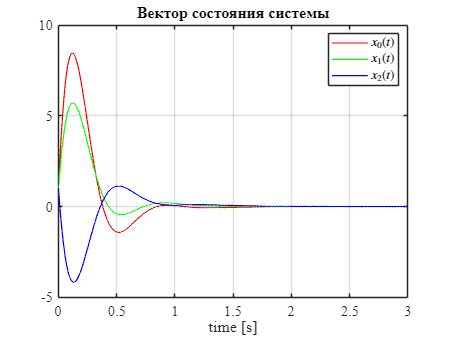


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x1");


%%%%%%%%%%%%%%%%%%%%%%
mu = 10;
x0 = [1 ; 0; 0];
cvx_begin sdp
variable P(3,3) symmetric  % Declare P as symmetric
P >= 0.0001 * eye(3);
variable Y(1,3) 

P*A' + A*P + 2*alpha*P + Y'*B' + B*Y <= 0;
[P x0;
 x0' 1] > 0;
[P Y';
Y mu^2] >0;
cvx_end

 
Calling SDPT3 4.0: 32 variables, 9 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  9
 dim. of sdp    var  = 14,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.6e+02|1.9e+00|5.8e+03| 1.009987e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.712|0.835|1.3e+02|3.1e-01|1.5e+03| 3.488748e+02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.635|0.486|4.9e+01|1.6e-01|7.8e+02| 1.779100e+02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.866|0.762|6.5e+00|3.8e-02|1.3e+02| 6.690142e+00  0.000000e+

K = Y*P^-1 % K2

K =     4.0009   -4.1716    3.6506



EIG_K2 = eig(A+B*K)

EIG_K2 =   -2.3728 + 5.2541i
  -2.3728 - 5.2541i
  -2.0000 + 0.0000i


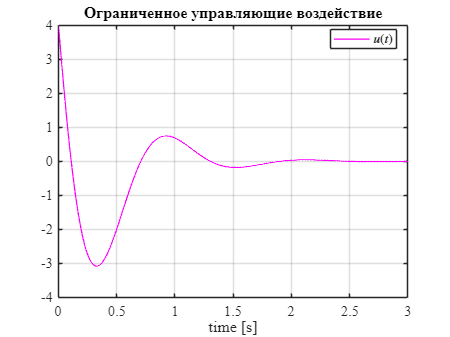


out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Ограниченное управляющие воздействие')
save_file("ctrl1_u2");

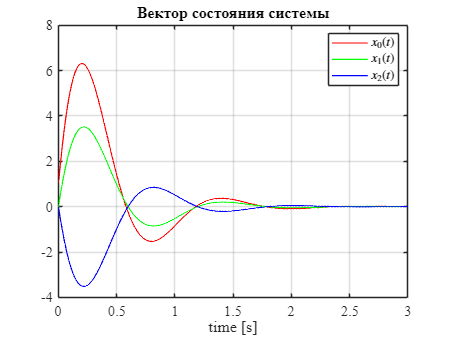


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x2");

## Второй выбор альфа

simTimeStart = 0;
simTimeEnd = 12;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

alpha = 0.5; % desired decay rate

% Lyapunov inequality
cvx_begin sdp
variable P(3,3) symmetric  % Declare P as symmetric
P >= 0.0001 * eye(3);
variable Y(1,3) 

P*A' + A*P + 2*alpha*P + Y'*B' + B*Y <= 0;
cvx_end

 
Calling SDPT3 4.0: 15 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of free   var  =  3 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.1e+02|2.0e+02|4.1e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.905|0.873|3.0e+01|2.6e+01|2.7e+02| 0.000000e+00  4.286688e-03| 0:0:00| chol  1  1 
 2|0.965|0.907|1.0e+00|2.4e+00|2.0e+01| 0.000000e+00  4.322842e-03| 0:0:00| chol  1  1 
 3|1.000|0.937|5.3e-04|1.5e-01|1.2e+00| 0.000000e+00  6.840237e-04| 0:0:00| 

K = Y*P^-1

K =     6.6484   -6.3171    6.2755



EIG_K1 = eig(A+B*K) % K1

EIG_K1 =   -4.5082 + 5.5042i
  -4.5082 - 5.5042i
  -2.0000 + 0.0000i


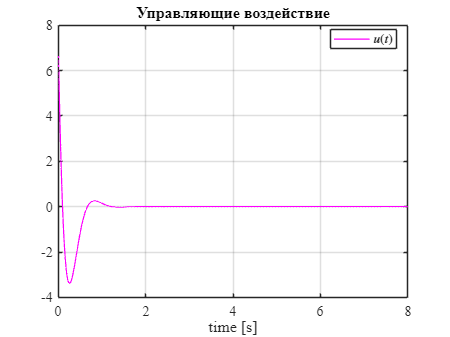



out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl1_u3");

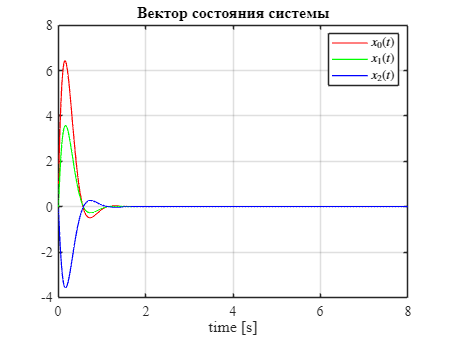


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x3");


%%%%%%%%%%%%%%%%%%%%%%
mu = 22;
x0 = [1 ; 0; 0];
cvx_begin sdp
variable P(3,3) symmetric  % Declare P as symmetric
P >= 0.0001 * eye(3);
variable Y(1,3) 

P*A' + A*P + 2*alpha*P + Y'*B' + B*Y <= 0;
[P x0;
 x0' 1] > 0;
[P Y';
Y mu^2] >0;
cvx_end

 
Calling SDPT3 4.0: 32 variables, 9 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  9
 dim. of sdp    var  = 14,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.6e+02|1.7e+00|2.1e+04| 4.849993e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.538|0.864|2.1e+02|2.4e-01|6.1e+03| 2.386681e+03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.626|0.267|7.9e+01|1.7e-01|3.3e+03| 1.060228e+03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.749|0.973|2.0e+01|4.7e-03|6.9e+02| 2.900805e+02  0.000000e+

K = Y*P^-1 % K2

K =     1.7521   -2.3862    1.5194



EIG_K2 = eig(A+B*K)

EIG_K2 =   -1.0332 + 3.8682i
  -1.0332 - 3.8682i
  -2.0000 + 0.0000i


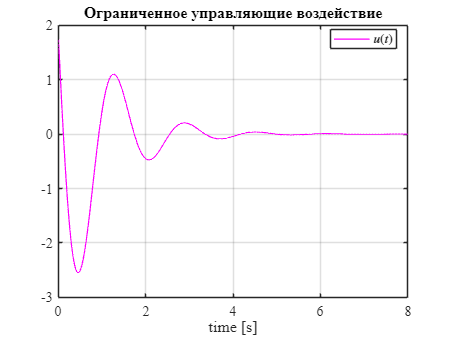


out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Ограниченное управляющие воздействие')
save_file("ctrl1_u4");

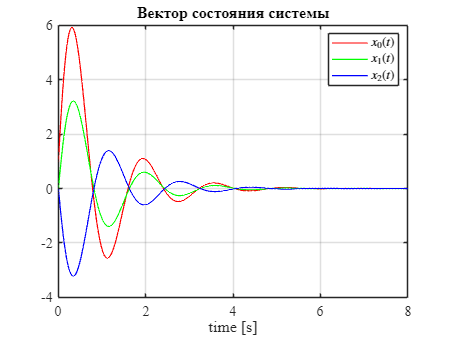


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x4");

## Для каждого из выбранных значений α синтезировать регулятор, обеспечивающий заданную степень устойчивости, при помощи матричного уравнения типа Риккати

Так как у нас система стабилизируема, то лучше применить **усечение системы,**

иначе численные методы вообще не работают и чемодан вокзал россия...

Начальные условия этого пункта задания

nu = 2; R = 1;

## Alpha = 2, Q = I

simTimeStart = 0;
simTimeEnd = 3;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

alpha = 2; % desired decay rate
Q = eye(2);

[P,Aj] = jordan(A)

P =   -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


[P2, Aj2] = cdf2rdf(P,Aj)

P2 =    -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 =     -2     0     0
     0     3    -3
     0     3     3



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 
 
Aj1=P1^-1*A*P1 

Aj1 =     -2     0     0
     0     3     3
     0    -3     3



A_reduced = inv(P1) * A * P1 ; A_reduced(1,:)=[]; A_reduced(:,1)=[]

A_reduced =      3     3
    -3     3


B_reduced = inv(P1) * B ; B_reduced(1,:) = []

B_reduced =      1
    -7



Aa = A_reduced + eye(2)*alpha;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*B_reduced, Q, R);
K = -inv(R) * B_reduced' * P

K =     3.5912    2.3945


eig(A_reduced + B_reduced*K)

ans =   -3.5850 + 6.9453i
  -3.5850 - 6.9453i



eig(A_reduced + B_reduced * K)

ans =   -3.5850 + 6.9453i
  -3.5850 - 6.9453i


K_pad = [0 K]

K_pad =          0    3.5912    2.3945


K = K_pad * inv(P1)

K =     7.1825   -5.9857    7.1825


EIG_K3 =  eig(A + B * K) % K3

EIG_K3 =   -3.5850 + 6.9453i
  -3.5850 - 6.9453i
  -2.0000 + 0.0000i


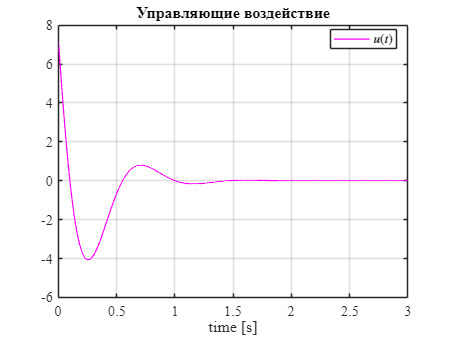



out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl1_u5");

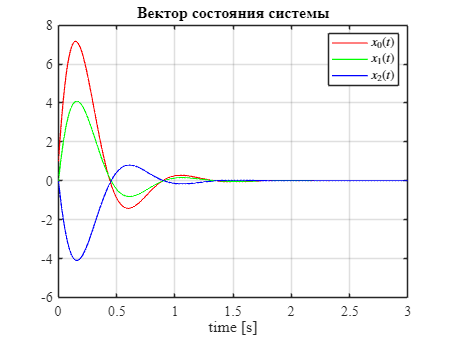


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x5");

## Alpha = 0.5, Q = I

simTimeStart = 0;
simTimeEnd = 12;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

alpha = 0.5;
Q = eye(2);

[P,Aj] = jordan(A)

P =   -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


[P2, Aj2] = cdf2rdf(P,Aj)

P2 =    -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 =     -2     0     0
     0     3    -3
     0     3     3



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 
 
Aj1=P1^-1*A*P1 

Aj1 =     -2     0     0
     0     3     3
     0    -3     3



A_reduced = inv(P1) * A * P1 ; A_reduced(1,:)=[]; A_reduced(:,1)=[]

A_reduced =      3     3
    -3     3


B_reduced = inv(P1) * B ; B_reduced(1,:) = []

B_reduced =      1
    -7



Aa = A_reduced + eye(2)*alpha;
[P, ~, EIG2] = icare(Aa, sqrt(nu)*B_reduced, Q, R);
K = -inv(R) * B_reduced' * P

K =     2.2239    1.8479


eig(A_reduced + B_reduced*K)

ans =   -2.3557 + 5.7062i
  -2.3557 - 5.7062i



eig(A_reduced + B_reduced * K)

ans =   -2.3557 + 5.7062i
  -2.3557 - 5.7062i


K_pad = [0 K]

K_pad =          0    2.2239    1.8479


K = K_pad * inv(P1)

K =     4.4477   -4.0718    4.4477


EIG_K4 =  eig(A + B * K) % K4

EIG_K4 =   -2.3557 + 5.7062i
  -2.3557 - 5.7062i
  -2.0000 + 0.0000i


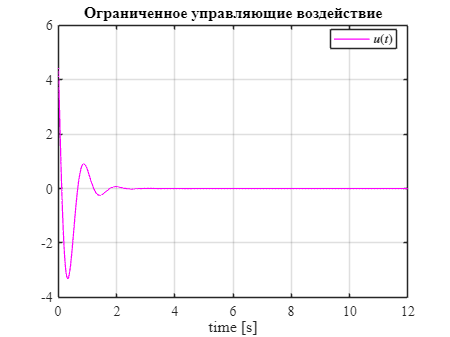


out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Ограниченное управляющие воздействие')
save_file("ctrl1_u6");

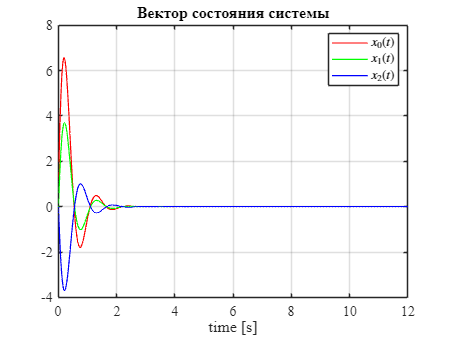


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x6");

## Alpha = 2, Q = 0

simTimeStart = 0;
simTimeEnd = 3;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

alpha = 2; % desired decay rate
Q = zeros([2,2]);

[P,Aj] = jordan(A)

P =   -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


[P2, Aj2] = cdf2rdf(P,Aj)

P2 =    -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 =     -2     0     0
     0     3    -3
     0     3     3



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 
 
Aj1=P1^-1*A*P1 

Aj1 =     -2     0     0
     0     3     3
     0    -3     3



A_reduced = inv(P1) * A * P1 ; A_reduced(1,:)=[]; A_reduced(:,1)=[]

A_reduced =      3     3
    -3     3


B_reduced = inv(P1) * B ; B_reduced(1,:) = []

B_reduced =      1
    -7



Aa = A_reduced + eye(2)*alpha;
[P, ~, EIG1] = icare(Aa, sqrt(nu)*B_reduced, Q, R);
K = -inv(R) * B_reduced' * P

K =     2.1333    1.7333


eig(A_reduced + B_reduced*K)

ans =   -2.0000 + 5.8310i
  -2.0000 - 5.8310i



eig(A_reduced + B_reduced * K)

ans =   -2.0000 + 5.8310i
  -2.0000 - 5.8310i


K_pad = [0 K]

K_pad =          0    2.1333    1.7333


K = K_pad * inv(P1)

K = 1×3
    4.2667   -3.8667    4.2667


EIG_K3 =  eig(A + B * K) % K3

EIG_K3 = 3×1
  -2.0000 + 5.8310i
  -2.0000 - 5.8310i
  -2.0000 + 0.0000i


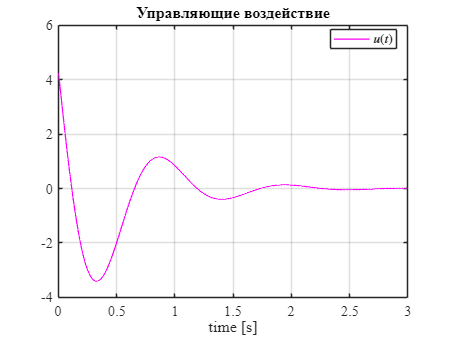



out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Управляющие воздействие')
save_file("ctrl1_u7");

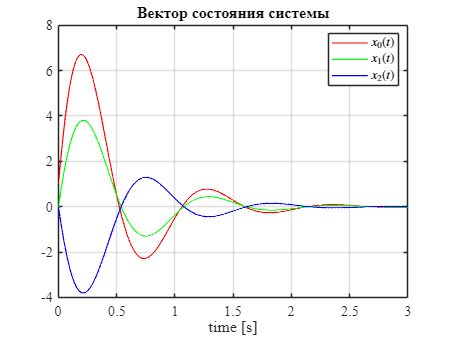


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x7");

## Alpha = 0.5, Q = 0

simTimeStart = 0;
simTimeEnd = 12;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_controller'; 
load_system(modelName);

alpha = 0.5;

Q = zeros([2,2]);

[P,Aj] = jordan(A)

P = 3×3
  -1.0000 + 0.0000i  -1.5000 + 0.5000i  -1.5000 - 0.5000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


Aj = 3×3
  -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   3.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.0000 + 3.0000i


[P2, Aj2] = cdf2rdf(P,Aj)

P2 = 3×3
   -1.0000   -2.1213    0.7071
         0   -1.4142         0
    1.0000    1.4142         0


Aj2 = 3×3
    -2     0     0
     0     3    -3
     0     3     3



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 
 
Aj1=P1^-1*A*P1 

Aj1 = 3×3
    -2     0     0
     0     3     3
     0    -3     3



A_reduced = inv(P1) * A * P1 ; A_reduced(1,:)=[]; A_reduced(:,1)=[]

A_reduced = 2×2
     3     3
    -3     3


B_reduced = inv(P1) * B ; B_reduced(1,:) = []

B_reduced = 2×1
     1
    -7



Aa = A_reduced + eye(2)*alpha;
[P, ~, EIG2] = icare(Aa, sqrt(nu)*B_reduced, Q, R);
K = -inv(R) * B_reduced' * P

K = 1×2
    1.0033    1.1433


eig(A_reduced + B_reduced*K)

ans = 2×1
  -0.5000 + 4.6098i
  -0.5000 - 4.6098i



eig(A_reduced + B_reduced * K)

ans = 2×1
  -0.5000 + 4.6098i
  -0.5000 - 4.6098i


K_pad = [0 K]

K_pad = 1×3
         0    1.0033    1.1433


K = K_pad * inv(P1)

K = 1×3
    2.0067   -2.1467    2.0067


EIG_K4 =  eig(A + B * K) % K4

EIG_K4 = 3×1
  -0.5000 + 4.6098i
  -0.5000 - 4.6098i
  -2.0000 + 0.0000i


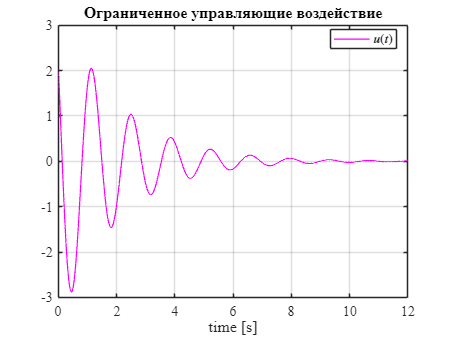


out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Ограниченное управляющие воздействие')
save_file("ctrl1_u8");

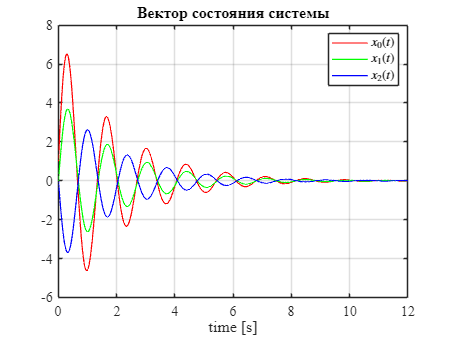


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_plant(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, x_plant(:,2), 'g', 'LineWidth', 1.0); 
plot(time, x_plant(:,3), 'b', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$x_0(t)$','$x_1(t)$','$x_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор состояния системы');
save_file("ctrl1_x8");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab9\latex9\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end